**Part 1**

Q1

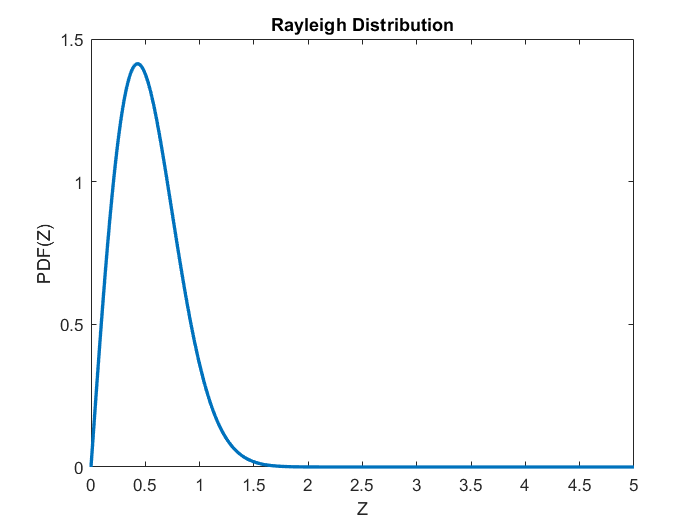

meanZ = sqrt(pi/2);
varZ = 2 - meanZ^2;

z = 0:0.01:5;
pdfZ = raylpdf(z, varZ);
plot(z, pdfZ, 'LineWidth', 2);
xlabel('Z');
ylabel('PDF(Z)');
title('Rayleigh Distribution');

disp(['Mean of PDF(Z): ', num2str(meanZ)]);

Mean of PDF(Z): 1.2533


disp(['Variance of PDF(Z): ', num2str(varZ)]);

Variance of PDF(Z): 0.4292


Q2

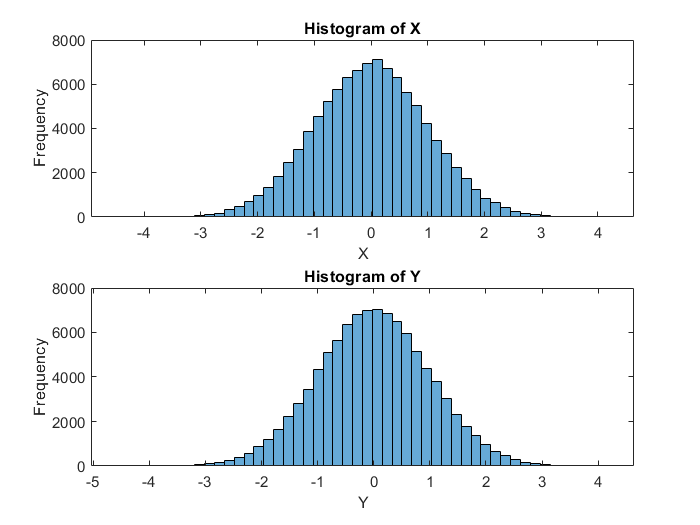

mu = 0;
sigma = 1;

N = 100000;
X = normrnd(mu, sigma, [1, N]);
Y = normrnd(mu, sigma, [1, N]);

figure;
subplot(2, 1, 1);
histogram(X, 50);
xlabel('X');
ylabel('Frequency');
title('Histogram of X');

subplot(2, 1, 2);
histogram(Y, 50);
xlabel('Y');
ylabel('Frequency');
title('Histogram of Y');

Q3

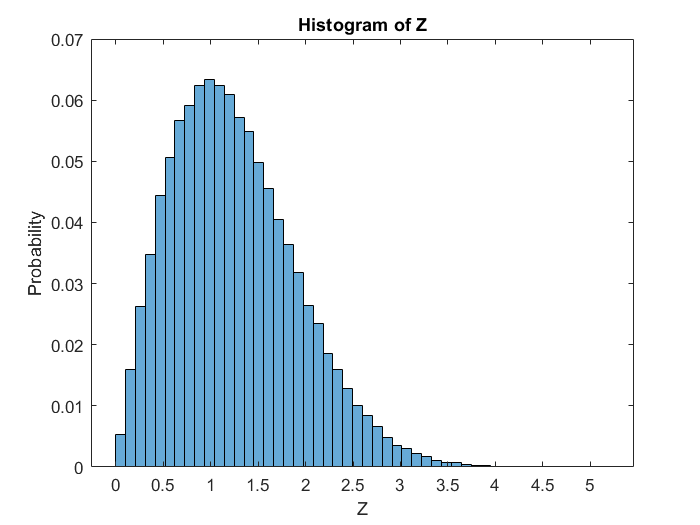

meanZ = sqrt(pi/2);
varZ = (4 - pi) / 2;

N = 100000;

X = normrnd(0, 1, [1, N]);
Y = normrnd(0, 1, [1, N]);

Z = sqrt(X.^2 + Y.^2);

figure;
histogram(Z, 50, 'Normalization', 'probability');
xlabel('Z');
ylabel('Probability');
title('Histogram of Z');


mean_Z = mean(Z);
var_Z = var(Z);

disp(['Mean of the generated sequence: ', num2str(mean_Z)]);

Mean of the generated sequence: 1.2528


disp(['Variance of the generated sequence: ', num2str(var_Z)]);

Variance of the generated sequence: 0.42999


**Part 2**

Q1

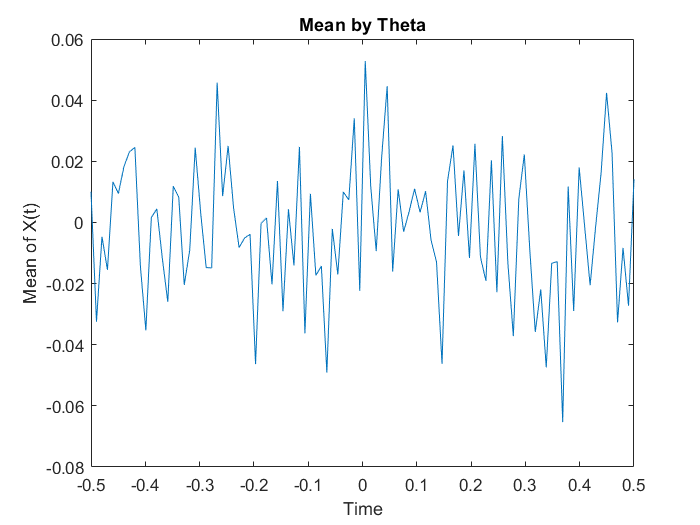

A = 10;
fs = 100;
w0 = 5*pi;
N = 10^5;
t = linspace(-0.5, 0.5, fs);

theta_per_time = zeros(fs, N);

for i = 1:fs
    theta_per_time(i, :) = normrnd(0, 2*pi, [1, N]);
end

X = A*cos(w0*t' + theta_per_time);

figure;
plot(t, mean(X,2));
xlabel('Time');
ylabel('Mean of X(t)');
title('Mean by Theta');

Q2

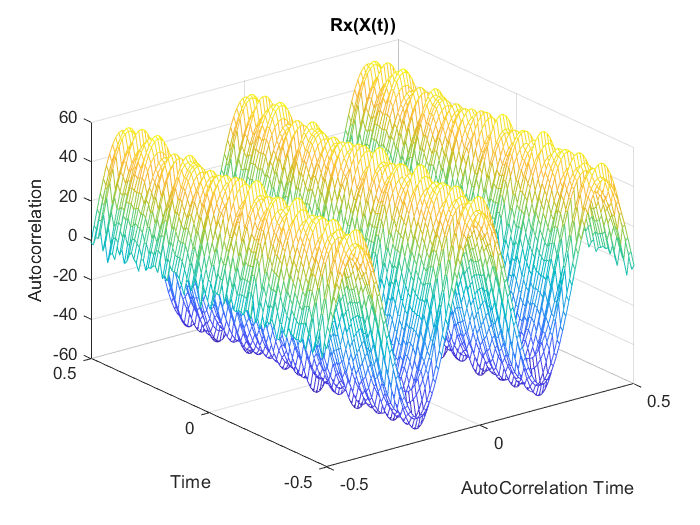

t_R_x = linspace(-0.5, 0.5, fs);

R_X = zeros(fs, fs);

for i = 1:100
    for j = 1:100
        temp = 10 * cos(w0 .* t(i) + theta_per_time(:, i));
        R_X(i, j) = mean(temp .* (10 * cos(theta_per_time(:, i) + w0 .* (t(i) + t_R_x(j)))));
    end
end

figure;
mesh(t_R_x, t, R_X);
xlabel('AutoCorrelation Time');
ylabel('Time');
zlabel('Autocorrelation');
title('Rx(X(t))');

Q3

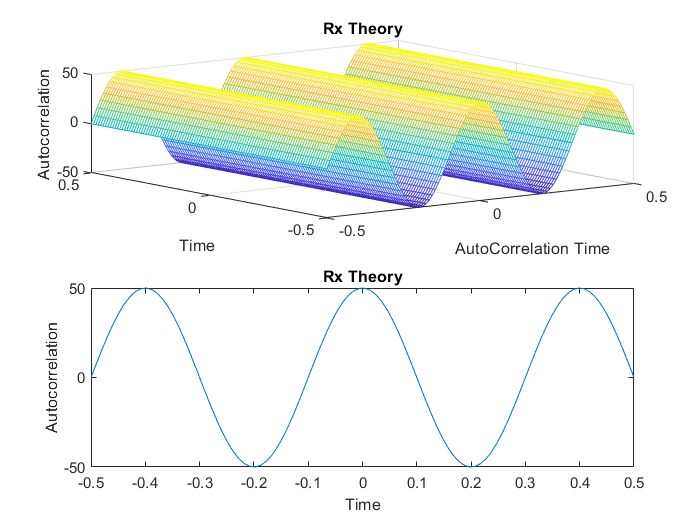

R_x_theory = A^2/2 * ones(fs, 1) * cos(w0 .* t_R_x);
R_x_theory2 = A^2/2 * cos(w0 .* t_R_x);
X_ave = zeros(1, 100);

figure;
subplot(2,1,1);
mesh(t_R_x, t, R_x_theory);
xlabel('AutoCorrelation Time');
ylabel('Time');
zlabel('Autocorrelation');
title('Rx Theory');
subplot(2,1,2);
plot(t, R_x_theory2);
xlabel('Time');
ylabel('Autocorrelation');
title('Rx Theory');

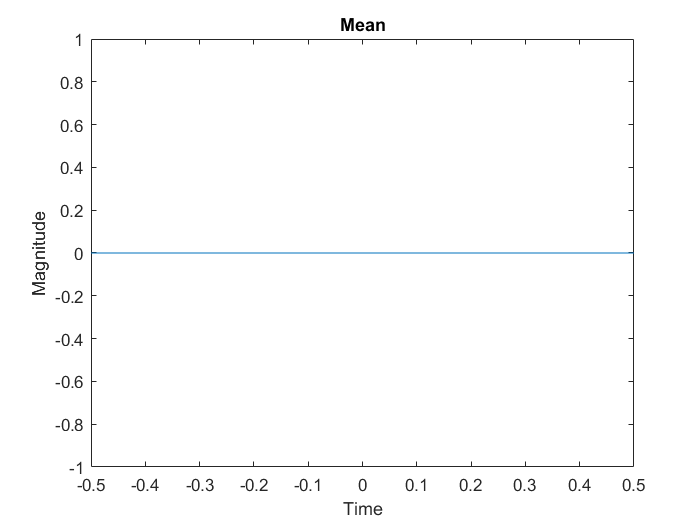

figure;
plot(t, X_ave);
xlabel('Time');
ylabel('Magnitude');
title('Mean');

Q5

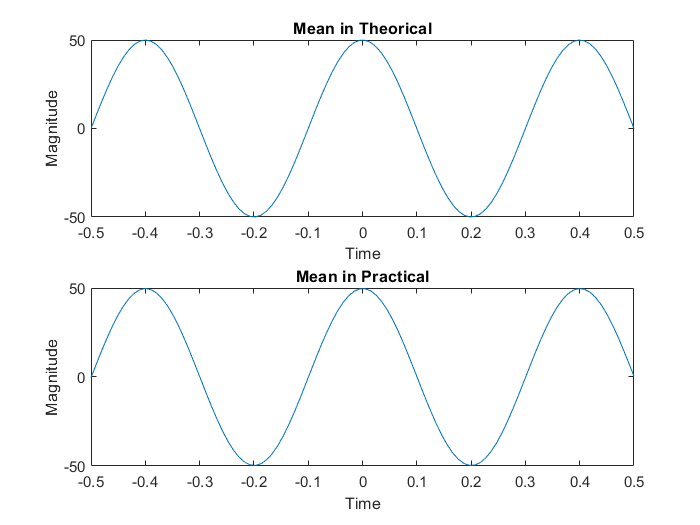

subplot(2,1,1);
plot(t, mean(R_x_theory));
xlabel('Time');
ylabel('Magnitude');
title('Mean in Theorical');
subplot(2,1,2);
plot(t, mean(R_X));
xlabel('Time');
ylabel('Magnitude');
title('Mean in Practical');
ylim([-50,50])

**Part C**

Q1

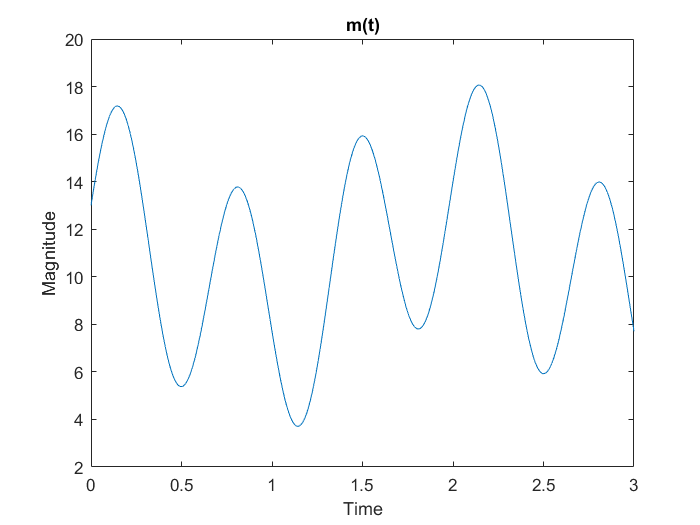

N = 50000;
t = linspace(0,3,N);
m_t = 10 + 5 .* sin(3*pi*t) + 3 .* (cos(pi*t).^3) + sin(pi*t/4);
figure
plot(t,m_t);
title("m(t)");
xlabel("Time");
ylabel("Magnitude");

Q2

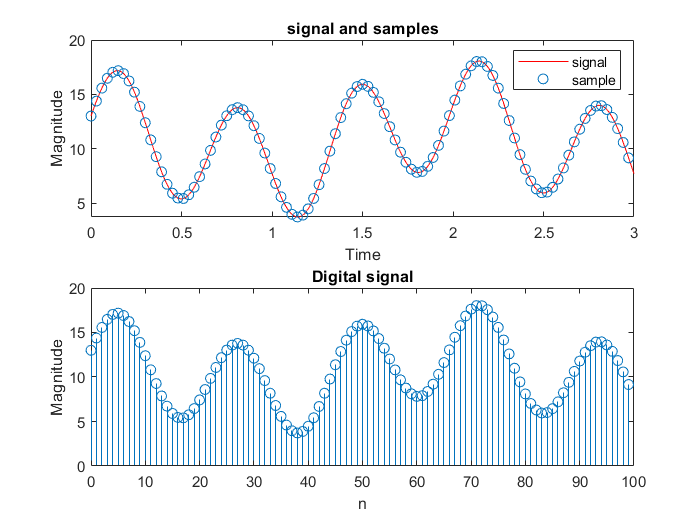

fs = 500;
m_sampled = m_t(1:fs:length(m_t));
n = 0:1:(length(m_sampled) - 1);
subplot(2,1,1);
plot(t,m_t,'r',t(1:fs:length(m_t)),m_sampled,'o');
title("signal and samples");
legend('signal','sample');
xlabel("Time");
ylabel("Magnitude");
subplot(2,1,2);
stem(n,m_sampled);
title("Digital signal");
xlabel("n");
ylabel("Magnitude");

Q3

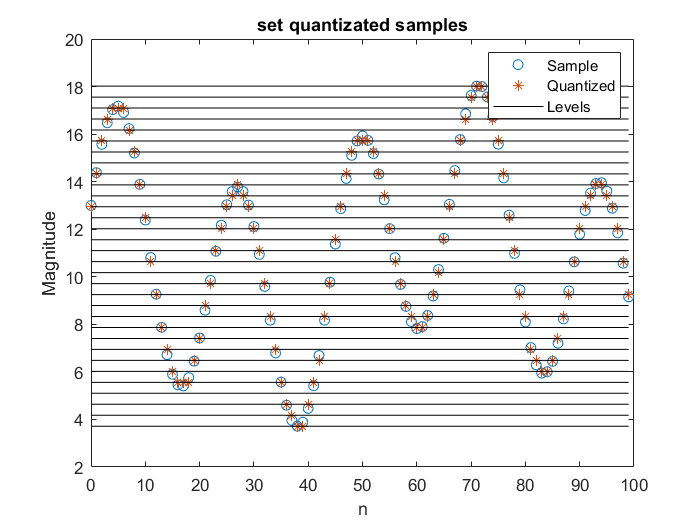

q = 32;
q_lev = linspace(min(m_sampled),max(m_sampled),q);
rows = q_lev'*ones(1,length(n));
m_q = q_lev(end) * ones(1,length(n));
for i = 1:length(n)
    for j = 1:q-1
        delta_q = q_lev(j + 1) - q_lev(j);
        if(m_sampled(i)>=q_lev(j) && m_sampled(i) < q_lev(j + 1))
            image = floor(2 * (m_sampled(i) - q_lev(j)) / delta_q);
        m_q(i) = q_lev(j) + image * (q_lev(j + 1) - q_lev(j));
        end
    end
end
figure
plot(n,m_sampled,'o',n,m_q,'*',n,rows,'black');
legend('Sample','Quantized','Levels');
title("set quantizated samples");
xlabel("n");
ylabel("Magnitude");

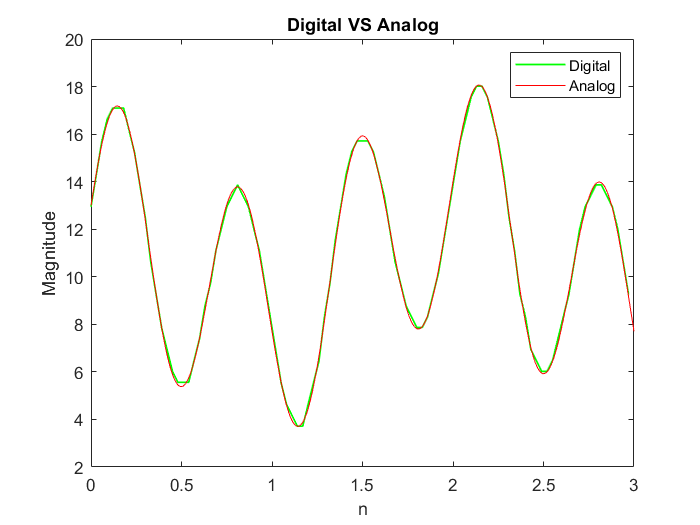


figure
plot(n*3/100, m_q, 'g', 'LineWidth', 1);
hold on;
plot(t, m_t, 'red');
legend('Digital','Analog');
title("Digital VS Analog");
xlabel("n");
ylabel("Magnitude");

Q4

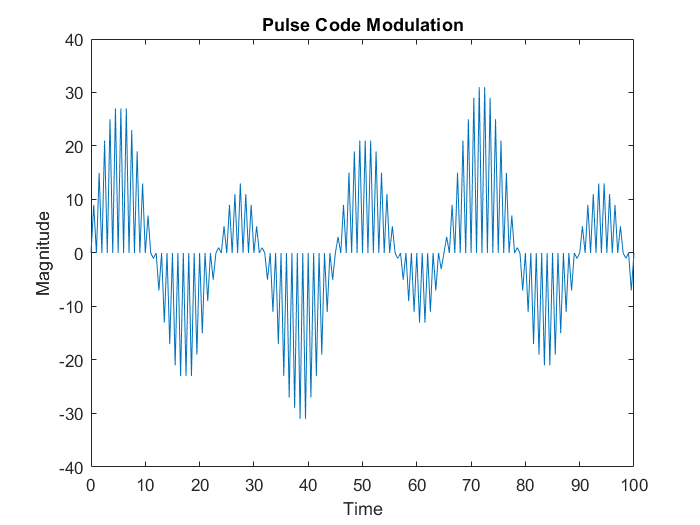

fs = 1000;
load("p.mat");
t = 1/fs:1/fs:1;
energy = sum(p.^2);
Dig = 0:1:q-1;
domain = -31:2:31;
gray_code = dec2bin(bin2gray(Dig','pam',32),5);
PCM = [];
pcm_t = [];
gray_pcm = [];
lev_gray = [q_lev;Dig;domain];
for i = 1:length(m_q)
 j = find(lev_gray(1,:) == m_q(i));
 PCM((i - 1) * length(p) + 1:i * length(p)) = p * lev_gray(3,j);
 pcm_t((i - 1) * length(p) + 1:i * length(p)) = (i - 1) + t;
 gray_pcm = [gray_pcm ; gray_code(j,:)];
end
figure;
plot(pcm_t,PCM);
title("Pulse Code Modulation");
xlabel("Time");
ylabel("Magnitude");

Q5

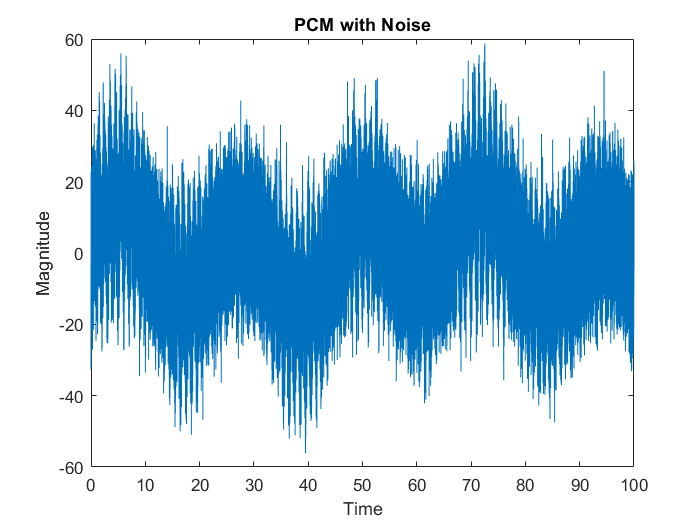

SNR_dB = 20;
SNR = 10 ^ (SNR_dB / 10);
N = length(p);
sigma = sum(PCM.^2) / N;
mu = 0;
noise = normrnd(mu,sqrt(sigma/SNR),[1 length(PCM)]);
noise_pcm = noise + PCM;
figure
plot(pcm_t,noise_pcm);
title("PCM with Noise");
xlabel("Time");
ylabel("Magnitude");

Q6

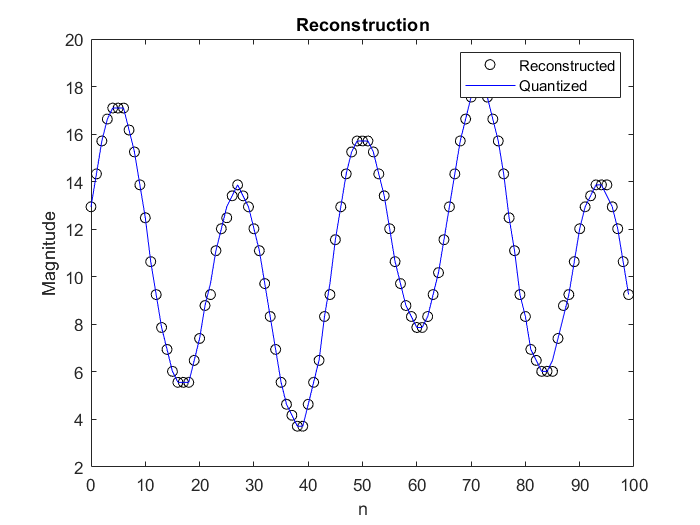

mu_ = zeros(1,length(noise_pcm) * 1/1000);
for i = 1:length(mu_)
    mu_(i) = sum(p.*noise_pcm((i-1)*length(p)+1:i*length(p)));
end
A = mu_/sum(p.^2);
Norm_A = zeros(1,length(A));
rec_qua = zeros(1,length(A));
for i = 1:length(A)
    [~, m] = max(A(i) >= lev_gray(3,:));
    m = min(m, q-1); 
    Norm_A(i) = lev_gray(3,m) + (A(i) - lev_gray(3,m)) / (lev_gray(3,m+1) - lev_gray(3,m)) * (lev_gray(3,m+1) - lev_gray(3,m));
    [~, j] = min(abs(lev_gray(3,:) - Norm_A(i)));
    rec_qua(i) = lev_gray(1,j);
end
figure
plot(n, rec_qua, 'blacko', n, m_q, 'b');
legend('Reconstructed','Quantized');
title("Reconstruction");
xlabel("n");
ylabel("Magnitude");

error = sum(rec_qua ~= m_q)

error = 6

Q7

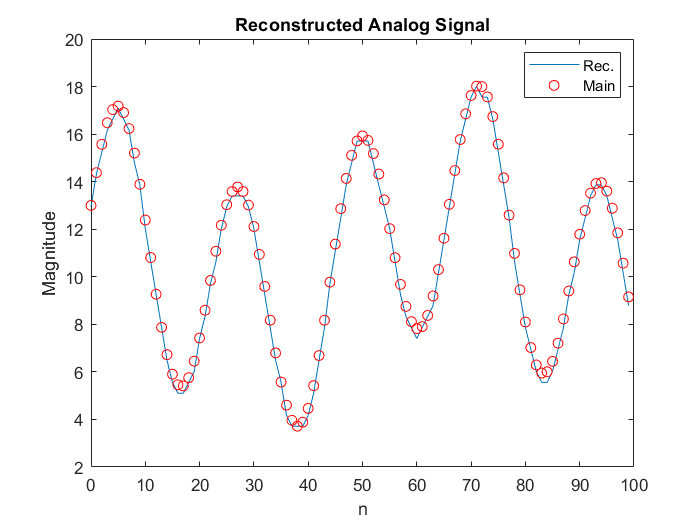

%fs = 500; %sampling rate
%signal1 = signal1(1:fs:length(signal1));
%n = 0:1:(length(signal1) - 1);

%levels = levels'*ones(1,length(n));

%intersections = [];
%figure;
%plot(n,signal1,'b.',n,levels,'black');
%for i = 1:100
%    for j = 1:32
%        if signal1(i) == levels(j,i)
%            intersections(end+1) = i;
%            hold on
%            plot(n(i),signal1(i),'ro')
%
%        end
%    end
%end

%x_spline = n(intersections);
%y_spline = signal1(intersections);

% use spline function
%t_spline = linspace(min(x_spline), max(x_spline), 100);
 

%spline = spline(x_spline, y_spline, t_spline);


%plot(t_spline,spline,'r-'); 

%xlabel('Samples')
%ylabel('Amplitude') 
%title('Signal Intersections with Spline')
%hold off
%------------------------
signal1 = m_sampled;
levels = q_lev;

sp = spline(1:length(levels), levels);
m_reconstructed = zeros(size(signal1));
error = 0;

for i = 1:length(signal1)
    [~, index] = histc(signal1(i), levels);
    m_reconstructed(i) = ppval(sp, index);    
    error = error + (m_reconstructed(i) - signal1(i))^2;
end

mse = error / length(signal1);

figure;
plot(n, m_reconstructed, n, signal1, 'ro');
legend('Rec.', 'Main');
xlabel('n');
ylabel('Magnitude');
title('Reconstructed Analog Signal');


mse

mse = 0.0711